# Analyse spectrale des signaux numériques

**But : **Ce TP débutera par le calcul de la transformé de Fourier d’un signal discret en appliquant la définition vue dans le cours que l’on comparera au résultat obtenus avec l’algorithme de calcul rapide (fft) de la transformée de Fourier. La deuxième partie concerne l’application de l’analyse spectrale d’un signal sonore dans le but de le filtrer dans le domaine fréquentiel.

clc; clear; close all;

## Analyse spectrale d’un signal numérique (ex1)

Pour les signaux discrets de durée finie la transformée de Fourier peut être approximée comme montré dans le cours par:


$$X\left(\textrm{jf}\right)=T_e \;\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{j2}\pi {\textrm{fnT}}_e }$$


Pour l’exemple on va prendre un signal x[n] simple et bien connu, l’impulsion rectangulaire centrée en *n = 0* d’amplitude *A = 1* et de longueur d’impulsion $\Delta t=11\left\lbrack s\right\rbrack$ (premier échantillon à $n=-40$ et dernier échantillon à $n=+39$ comme montré dans la figure suivante). On prendra pour période d’échantillonnage *Te = 1 [s]*. Ce signal discret est le résultat de l’échantillonnage du signal continu $x\left(t\right)=\textrm{Arect}\left(t/\Delta t\right)$

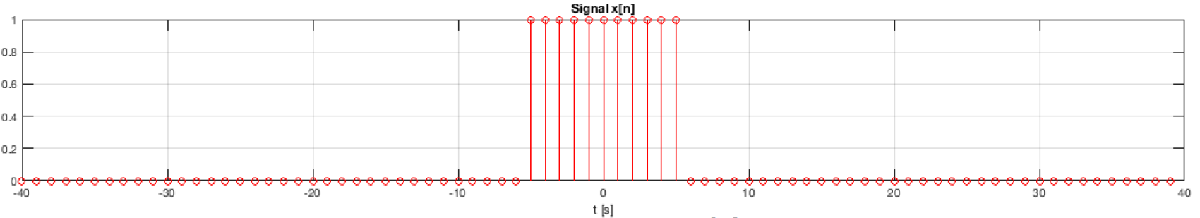

- Construisez le signal x[n] comme affiché ci-dessus:

% Votre code

La transformée de Fourier théorique du signal continu x(t) est donné par les tables et dans le cas présent vaut :


$$X_{\textrm{th}} \left(\textrm{jf}\right)=A\Delta t\cdot \textrm{sinc}\left(f\Delta t\right)$$


Dans cette relation la variable f est continue.

- Calculez le spectre théorique Xth et affichez le module dans une figure en faisant varier f entre fmin=-1 et fmax=1. Utilisez la fonction *sinc* de Matlab:

% Vote code

La formule de la transformée de Fourier définie précédement produit comme résultat un spectre continu pour toutes valeurs de fréquence f. Pratiquement, pour calculer la transformée de Fourier comme définie il est nécessaire de définir le pas fréquentiel $\Delta f$à utiliser qui peut être arbitrairement petit, on aimerait voir les passages par zéro du spectre qui se trouvent à Fz = 1/11, il faut donc choisir un sous multiple entier de Fz . Pour l’exemple prenons $\Delta f=\frac{1}{44}$.

Pour calculer la transformée de Fourier dans ce cas il est pratique de multiplier le vecteur ligne du signal x[n] par un vecteur ligne $w_{f_1 } \left\lbrack n\right\rbrack =T_e \;e^{-\textrm{j2}\pi \;f_1 {\textrm{nT}}_e }$ pour une fréquence particulière f1 qui nous intéresse. Donc on aura :


$$X\left\lbrack {\textrm{jf}}_1 \right\rbrack =x\left\lbrack n\right\rbrack \cdot w_{f_1 }^T \left\lbrack n\right\rbrack$$


Pour le calcul de tout le spectre il suffit alors de calculer pour toutes les fréquences désirées de *[-Fe ... + Fe]* par pas de $\Delta f$.

Si vous affichez le module du spectre obtenu par la formule de la TFD (équation du dessus) vous devez alors obtenir la figure suivante. Vous remarquerez que le spectre est périodique de période Fe, alors que le spectre théorique du signal continu, ne l’est pas.

- Calculez la TFD en utilisant une résolution spectrale 4 fois plus petite que l'intervalle des passages par zeros (par exemple:$\Delta f=\frac{1}{4*\Delta t}$) et affichez le module sur le même plot que le spectre théorique.

% votre code

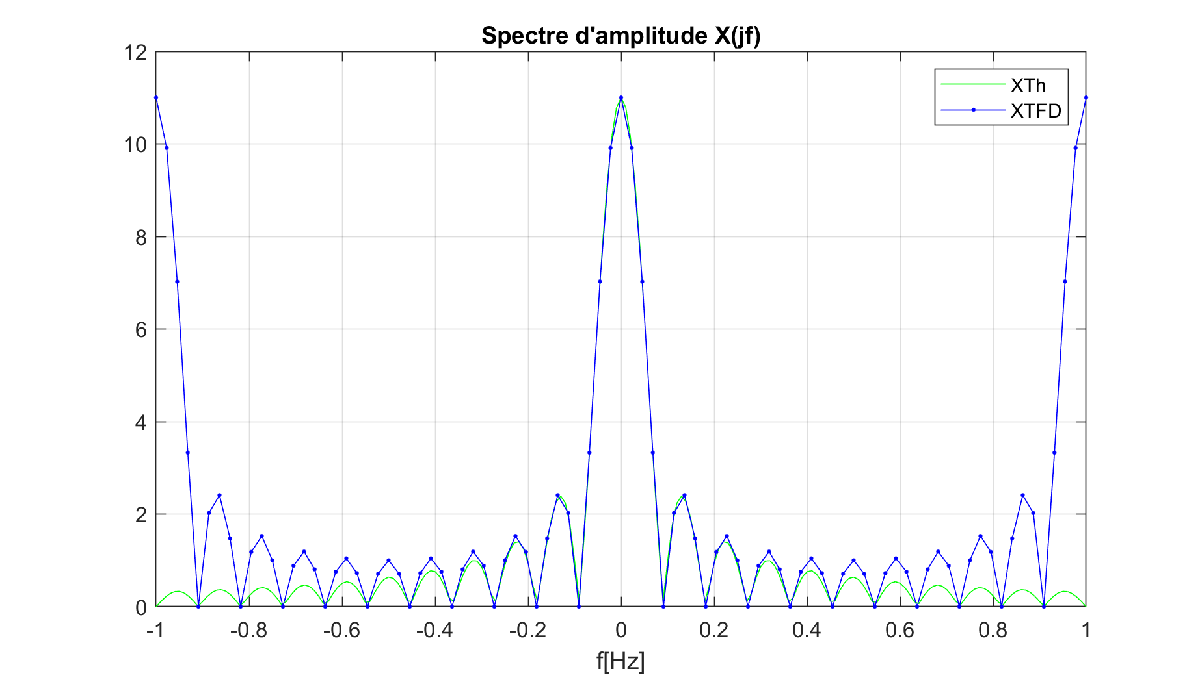

La fonction *fft()* permet le calcul rapide de la transformée de Fourier mais avec la contrainte $\Delta f=\frac{F_e }{N}$ dans notre cas$\Delta f=\frac{1}{80}=0\ldotp 0125\left\lbrack \textrm{Hz}\right\rbrack$. Entre autre le nombre de points du résultat est N et la plage de fréquence est $\left\lbrack -F_e /2\ldotp \ldotp \ldotp +F_e /2-\Delta f\right\rbrack$. Sa définition est la suivante :


$$X_D \left\lbrack \textrm{jk}\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-\textrm{j2}\pi \;\textrm{kn}/N}$$


Où k est l’index de fréquences $f=k\Delta f$, n est l’index du temps $t={\textrm{nT}}_e$ et *N* la longueur du signal. Les valeurs de $X_D$ ne sont pas les mêmes que ceux de *X(jf)*, un facteur d’échelle doit être appliqué et celui ci vaut Te.

L’utilisation est la suivante avec Matlab:

Si vous comparez le spectre trouvé par la fft et celui calculé par l’équation de la TFD vous obtenez la figure ci-dessous. Comme vous pouvez le remarquer les points ne sont pas placés aux mêmes fréquences, si bien que on n’a pas les passages par zéro du spectre avec la fft.

- Calculez le spectre avec la fft() et affichez le module du spectre sur le même plot que les précédent spectres.

% votre code

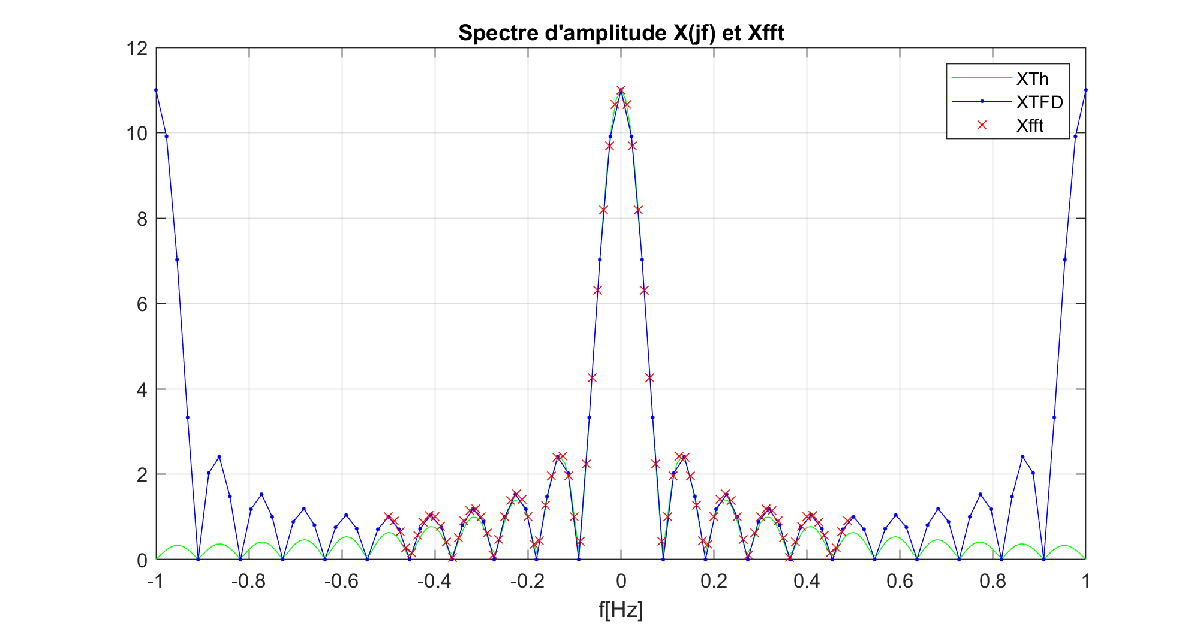

Repondez aux questions suivantes:

- Comment faire pour que les passages par zéro du spectre calculé avec la fft coïncident exactement avec les passages par zéro du spectre théorique ?

Il faut que la résolution spectrale (df) soit 1/M ou M est un multiple entier de la largeur du signal.

- Que se passe t’il si on allonge le signal x[n] de part et d’autre avec des échantillons nuls ?

Le spectre fréquentiel ne change pas vraiment.

- A quoi correspond la valeur X(0) ? 

C'est l'énergie du signal? NON! C'est la fréquence correspondant à la composante continue!

% Vos commentaires

## Filtrage dans le domaine fréquentiel (ex2)

### Signal carré

Le but est de creer un signal carré et de le filtrer en enlevant les fréquences supérieures à *fc*.

Pour ceci:

- 1) Créez un signal carré de fréquence f0 = 100Hz et de durée 1 seconde avec une fréquence d’échantillonnage $f_e =1/T_e =20\textrm{kHz}$. Tracez 10 périodes du signal xt dans la fenêtre subplot(2,2,1)

% votre code

- 2)  Écoutez le signal x(t) avec :

% votre code

- 3) Calculez son spectre Xjf et le vecteur fréquence ff avec les commandes (A quoi sert l'instruction fftshift?) :

- fftshift permet de centrer le signal autour de zéro

% votre code

- 4) Tracez son module dans la fenêtre *subplot(2,2,2).*

% votre code

- 5) Initialisez le spectre que vous allez filtrer :

% votre code

- 6) Modifiez ce spectre en annulant les composantes spectrales supérieures à fc = 500Hz. La fonction find est très utile dans ce cas. Tracez le module de ce spectre dans la fenêtre subplot(2,2,4).

% votre code

- 7) Construisez le signal temporel correspondant *xt_f* avec les commandes et Tracez ce signal filtré dans *subplot(2,2,3)* et écoutez le résultat du filtrage

% votre code

- 8) Modifiez la fréquence de coupure ; écoutez et commentez.

% vos observations

- 9) Ouvrez une nouvelle figure et tracez les spectrogrammes des deux signaux :

% votre code

- 10) Observez et commentez.

% vos observations

## Signal sonore (ex3)

Ces notions d’analyse fréquentielle et de filtrage connues, vous allez les appliquer à un signal sonore créé par vos soins. Pour ce faire, enregistrez une phrase de courte durée (1 à 3 secondes) avec une fréquence d’échantillonnage fe = 20 kHz:

Si vous n’avez pas la possibilité de enregistrer un son vous pouvez prendre le son comment.wav qui est un message de bienvenue. Si vous intéressez à l’analyse de sons de machine prenez le fichier motor.wav qui est un enregistrement d’un moteur à explosion. Pour lire les fichier audio utilisez :

% votre code

Puis :

- Tracez le signal (plot(xt)). Avec l’aide du zoom, relevez le domaine intéressant (n1, n2) du signal enregistré puis éliminez les parties inutiles et sauvegardez le signal dans un fichier .wav après l’avoir normalisé à 1 :

% votre code

- Calculez le vecteur temps tt et tracez xt dans la fenêtre subplot(2,2,1). Écoutez le signal.

% votre code

- Répétez sur votre phrase les opérations 3) à 10) appliquées préalablement au signal carré. Dans le cas de ce signal sonore, vous réaliserez un filtrage passe-bande plutôt qu’un simple passebas en annulant les composantes spectrales qui n’appartienent pas au domaine des fréquences téléphoniques $f_i =300H_z ,\;f_s =3\ldotp 5\textrm{kHz}$.

% votre code

- Comme le message vocal n’est pas stationnaire (il varie constamment en amplitude et en fréquence), il est nécessaire d’écourter la fenêtre d’analyse du spectrogramme. Vous prendrez donc Nspec = 256.

% votre code

- Observez, analysez et commentez.

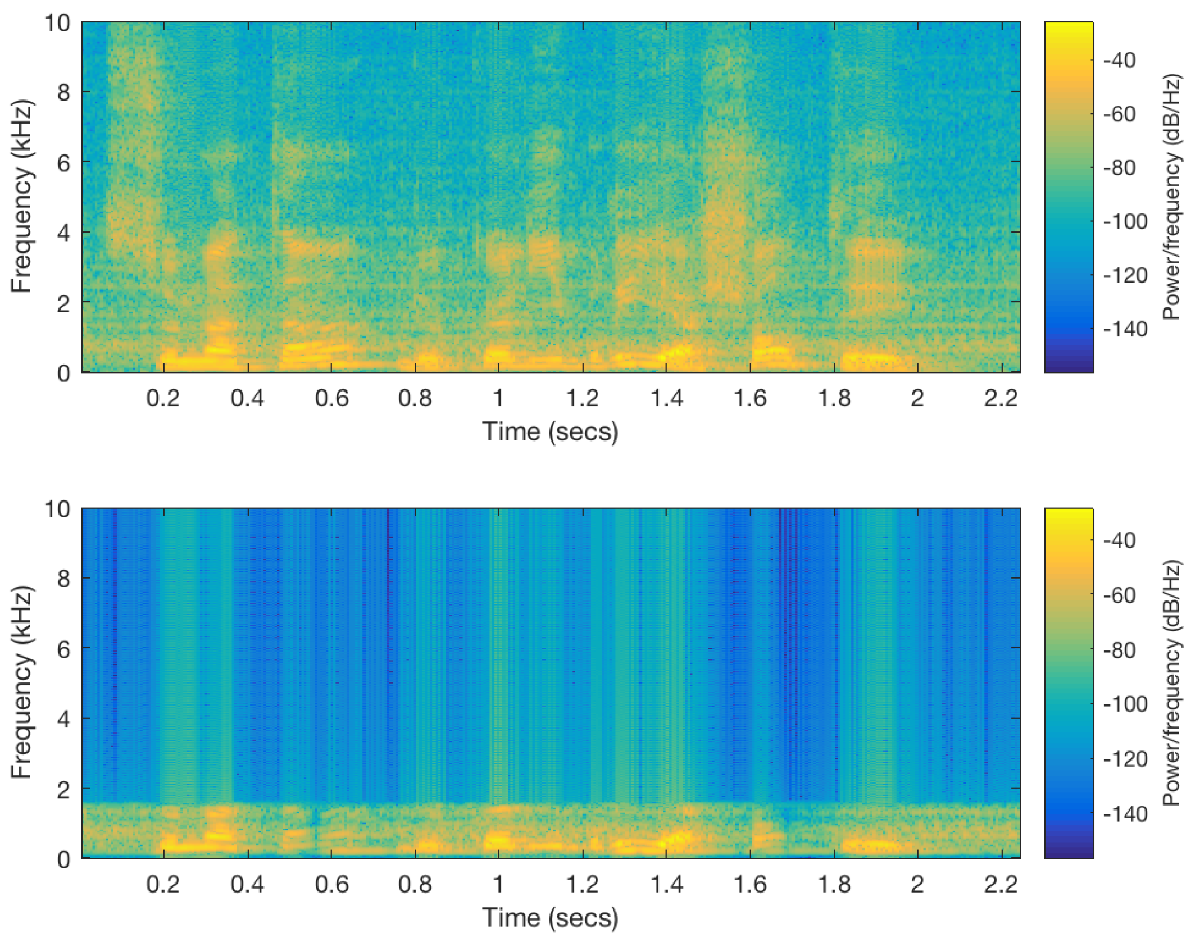

## Dé-bruitage par reconstruction d’un signal périodique (ex4)

Un capteur fournit un signal fortement bruité, on sait que ce signal contient un signal périodique à f0 = 50Hz (fréquence fondamentale) et plusieurs harmoniques. L’échantillonnage du signal analogique se fait à une fréquence fe = 5 [KHz]. La durée de l’enregistrement est de T = 510 [ms]. Le signal est montré dans la figure ci dessous.

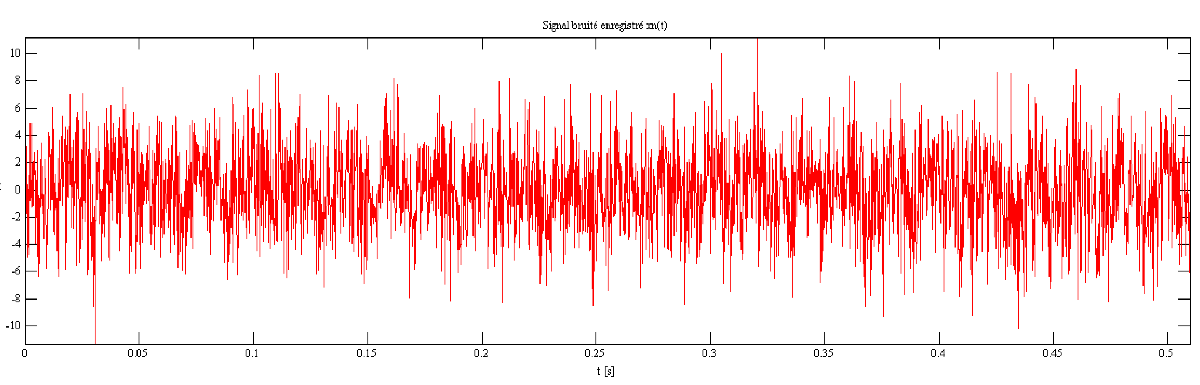

Le but de cette expérience est de retrouver le signal périodique sans bruit, sans utiliser les techniques de filtrage temporel ni fréquentiel vu précédemment. La technique que l’on va employer consiste à faire une analyse spectrale du signal pour retrouver les amplitudes et les phases de chacune des harmoniques, et ensuite reconstituer le signal périodique par synthèse numérique. Si on utilise sans précaution la TFD on remarque plusieurs pics qui ne correspondent pas exactement aux fréquences recherchés comme montré dans la figure ci-dessous :

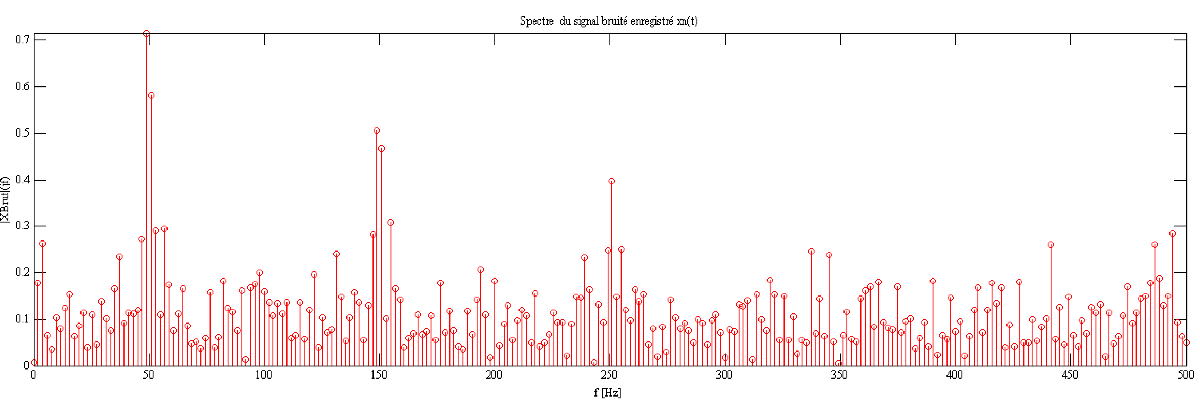

Le travail à réaliser est le suivant :

- Chargez le fichier '4-SignalBruite.mat' avec la fonction load(). Puis affichez le signal xn en fonction du temps.

- A l’aide de la FFT analysez le signal, veillez à choisir un pas fréquentiel $\Delta f$ en rapport aux fréquences du signal périodique dans le but de retrouver dans le spectre les 3 pics correspondants.

- Affichez le spectre unilatéral du module et de la phase, et détectez automatiquement les composantes de chaque harmonique.

- A partir du module et de la phase de chaque harmonique reconstruisez le signal non bruité et affichez le en superposition avec le signal bruité.

- Calculez la valeur efficace du signal, celle du bruit ( signal bruité - signal non bruité), et calculez le rapport signal sur bruit en [dB].

% votre code